# Segundo Parcial Robótica semestre 2025-2

## Simulación de trayectoria de un robot SCARA 3R en el plano

Alumnos: 

- Castañeda Coria Brenda Scarlett

- Juárez Ugalde Ricardo

- Parra García Horacio

## Resumen

En este reporte se documenta el proceso de simulación de un robot SCARA 3R en el plano, utilizando la máquina virtual proporcionada en la asignatura y dos entornos de simulación: Gazebo y RViz. Como parte fundamental del desarrollo, se aborda la resolución del modelo cinemático inverso de la postura, indispensable para generar las expresiones matemáticas necesarias en los archivos de simulación.

Se incluye una explicación sobre la estructura de los archivos URDF, así como del código que describe la configuración geométrica del robot SCARA 3R. Además, se plantea tanto el modelo cinemático directo como el inverso, retomando conceptos desarrollados en el primer examen parcial del curso.

Para definir la trayectoria del robot, se consultó el artículo titulado *"Optimum trajectory function for minimum energy requirements of a spherical robot"*, escrito por S. A. Alshahrani, H. Diken y A. A. N. Aljawi. En dicho artículo se presentan diversas funciones matemáticas para la generación de trayectorias óptimas. Se seleccionó la función denominada "Cubic Segment Trajectory", basada en un polinomio de tercer orden, la cual fue implementada en el modelo de cinemática inversa del robot para simular su desplazamiento entre un punto inicial y un punto final.

Finalmente, se utilizaron como referencia los archivos de nodos en Python desarrollados durante la asignatura, los cuales fueron adaptados para cargar la ecuación de la trayectoria y permitir la visualización del movimiento del robot en los entornos de simulación mencionados. La trayectoria propuesta demostró ser válida, ya que el robot logra ejecutar el movimiento planificado y alcanzar los puntos objetivo. No obstante, el análisis del índice de manipulabilidad reveló que la capacidad de movimiento del robot disminuye progresivamente al acercarse al punto final de la trayectoria, lo que podría considerarse un aspecto a mejorar en futuras versiones del planeamiento de trayectorias.

## Introducción

En la actualidad, el uso de robots industriales se ha vuelto esencial para llevar a cabo tareas de automatización que demandan precisión, repetibilidad y eficiencia. Entre estos, el robot SCARA (Selective Compliance Assembly Robot Arm) se distingue por su capacidad para realizar movimientos rápidos y precisos en el plano, lo que lo hace ideal para operaciones como ensamblaje, soldadura y manipulación de piezas. No obstante, con fines académicos, en este trabajo únicamente se abordará el trazo de una trayectoria con dicho robot, considerando de manera teórica su capacidad para mover un objeto.

El presente trabajo tiene como propósito simular y analizar el movimiento de un robot SCARA de tres grados de libertad (3R) en el plano, abarcando tanto su modelado matemático como su implementación en un entorno virtual. Para ello, se hace uso del simulador Gazebo y de la herramienta de visualización RViz, ambos integrados mediante ROS 2, tecnología utilizada y estudiada durante el desarrollo del curso.

Se plantean los modelos cinemáticos directo e inverso, fundamentales para el control preciso de la posición y orientación del robot. A partir de estos modelos, se implementa una trayectoria cúbica que permite al robot desplazarse suavemente desde un punto inicial hasta un punto final, cumpliendo con las condiciones físicas de continuidad en posición y velocidad. Toda esta información es integrada en un archivo URDF, que define el entorno de simulación del robot.

Adicionalmente, se analiza el comportamiento del robot a lo largo de la trayectoria mediante el cálculo del índice de manipulabilidad, una métrica que evalúa la capacidad del robot para moverse libremente en distintas direcciones desde una configuración determinada. Finalmente, se presenta la implementación de la trayectoria en código Python 3 y su ejecución en el simulador, lo que permite visualizar de manera gráfica el desempeño del robot dentro del entorno virtual.

**Hipótesis**

Existe una trayectoria definida mediante una función polinómica de tercer grado (cubic segment trajectory) que permite al robot SCARA 3R desplazarse desde un punto inicial P1 hasta un punto final P2 dentro de su espacio de trabajo. El cálculo de la cinemática inversa y del índice de manipulabilidad contribuirá a que los movimientos generados sean controlados, evitando singularidades y facilitando la ejecución correcta de la trayectoria planteada.

**Objetivo**

Diseñar e implementar una trayectoria cúbica (cubic segment trajectory) para un robot SCARA 3R que le permita desplazar un objeto desde un punto inicial P1 hasta un punto final P2 dentro de su espacio de trabajo. La trayectoria deberá garantizar un movimiento suave y continuo, evitando configuraciones singulares y asegurando que el índice de manipulabilidad "W" del robot se mantenga dentro de un rango adecuado, con el fin de conservar la capacidad de control y precisión del sistema durante toda la ejecución de la tarea.

### Metas

- Modelo cinemático directo e inverso del robot scara.

- El cálculo del índice de manipulabilidad.

- Determinar el tipo de trayectoría parámetrizada a utilizar ( investigar).

- Parámetros del robot y lugar geometrico de la trayectoría (fijos).

- Variables (Tiempo de ejecución)

- Simulaciones.

- Resultados.

- Conclusiones.

## Planteamiento de un robot 3R en el espacio mediante la creación de su URDF

El archivo URDF  "Unified Robot Description Format" (URDF)" es aquel que contiene la informacion base mínima para poder describir cualquier sistema mecanico en formato XML. Se apoya en generar geometrias por mallas.  Este se compone del nivel de invercia y del nivel visual. Este archivo cuenta de un encabezado en el que se indica la versión xml que se está utilizando. Para este caso se utilizó utf-8 que quiere decir 8-bit Unicode Transformation Format. 

Posteriormente inicia la descripción del robot del robot en la que primero se indica su nombre y el límite de este. En este apartado contiene la parte mecánica del robot. 

#### Eslabones:

Los eslabones se describen como "links". En estos se incluyen las propiedades inerciales y relaciones de colisión. Se puede ver que está compuesta por la parte visual, las relaciones de colisión y la inercial.

A continuación se muestra la definición del primer eslabón del robot a modelar.

#### **Visual:**

Define la apariencia del eslabón en 3 parámetros: pose, geometría y material. En la pose del eslabón está determinada la pisicón respecto al sistema inercial (en metros) y la orientación se determina utilizando la convención rpy (yaw, pitch and roll) en radianes.

`<``visual``>`

            `<``origin xyz``=``"``0.0 0.0 0.1``"`` rpy``=``"``0 0 0``"` `/``>`

            `<``geometry``>`

                `<``box size``=``"``0.1 0.15 0.2``"` `/``>`

            `<``/``geometry``>`

            `<``material name``=``"``grey``"``>`

                `<``color rgba``=``"``0.1 0.1 0.1 1.0``"` `/``>`

            `<``/``material``>`

        `<``/``visual``>`

***Geométrica: ***

Está definida por geometrías simples como cubos, prismas, cilindros y esferas. Puede ser definida por una malla exportada de un CAD. Para este ejemplo se definió como sigue:

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

***Material***`:`

En esta sección se define el color del eslabón y la transparencia. 

            `<``material name``=``"``grey``"``>`

                `<``color rgba``=``"``0.1 0.1 0.1 1.0``"` `/``>`

            `<``/``material``>`

El color se debe modificar modificando la intensidad de colores rgb en una escala del 0 al 1. Del mismo modo, la transparencia tiene una escala del 0 al 1. 

El código final en el que se muestran todas estas partes se muestra en el código a continuación.

`<link name="link_1">`

`        <visual>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`            <material name="red">`

`                <color rgba="1 0.0 0.0 1.0"/>`

`            </material>`

`        </visual>`

`        <collision>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`        </collision>`

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

`    </link>`

#### Colisión:

En esta parte se definen los límites físicos del eslabón cuando interactúa con otros elementos de su entorno. Se compone de la definición de los parámetros de origen y definición de geometría, estos son diferentes a los definidos en la parte visual. 

`        <collision>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`        </collision>`

#### Inercial:

La sección `<inertial>` dentro de la definición de un eslabón describe tanto la inercia lineal como la inercia rotacional del componente, considerando siempre su centro de masa.

Para caracterizar correctamente este comportamiento dinámico, es necesario especificar los siguientes elementos:

- La masa total del eslabón en kilogramos (kg).

- La posición del centro de masa del eslabón con respecto a su sistema de referencia, a través del elemento `<origin>`.

- Los componentes de la matriz de inercia, que representan la resistencia del cuerpo a cambios en su estado de rotación. Estos se expresan en kilogramos por metro cuadrado (kg·m²), siguiendo el sistema internacional de unidades (ISO).

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

#### Eslabón base:

El eslabón base es un eslabón fijo dentro del espacio de trabajo. Este es necesario en cada descripción de robots seriales o móviles. 

#### Juntas:

Las juntas son aquellas que permiten el movimiento relativo entre eslabones. De acuerdo al timpo de movimiento pueden ser: juntas rotacionales, juntas continuas, juntas prismáticas y juntas fijas. Para este caso utilizaremos juntas rotacionales. Estas son parecidas a las articulaciones en los brazos de los humanos. El código para las juntas es el siguiente. 

`    <joint name="link_1_joint" type="revolute">`

`        <parent link="base_link"/>`

`        <child link="link_1"/>`

`        <axis xyz="0 0 1"/>`

`        <limit lower="-3.14159" upper="3.14159" velocity="50.0" `

`               effort="1000.0"/>`

`        <origin xyz="0 0 0.225" rpy="0 0 0"/>`

`    </joint>`

#### Código completo:

`<?xml version="1.0" encoding="utf-8"?>`

`<!--Aqui comienza el robot-->`

`<robot name="robot_scara">`

`    <link name="base_link">`

`        <visual>`

`            <origin xyz="0.0 0.0 0.1" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.1 0.15 0.2" />`

`            </geometry>`

`            <material name="grey">`

`                <color rgba="0.1 0.1 0.1 1.0" />`

`            </material>`

`        </visual>`

`        <collision>`

`            <origin xyz="0.0 0.0 0.1" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.1 0.15 0.2" />`

`            </geometry>`

`        </collision>`

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

`    </link>`

`    <link name="link_1">`

`        <visual>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`            <material name="red">`

`                <color rgba="1 0.0 0.0 1.0"/>`

`            </material>`

`        </visual>`

`        <collision>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`        </collision>`

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

`    </link>`

`    <joint name="link_1_joint" type="revolute">`

`        <parent link="base_link"/>`

`        <child link="link_1"/>`

`        <axis xyz="0 0 1"/>`

`        <limit lower="-3.14159" upper="3.14159" velocity="50.0" `

`               effort="1000.0"/>`

`        <origin xyz="0 0 0.225" rpy="0 0 0"/>`

`    </joint>`

`    <link name="link_2">`

`        <visual>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`            <material name="green">`

`                <color rgba="0.0 1.0 0.0 1.0" />`

`            </material>`

`        </visual>`

`        <collision>`

`            <origin xyz="0.25 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.5 0.05 0.05" />`

`            </geometry>`

`        </collision>`

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

`    </link>`

`    <joint name="link_2_joint" type="revolute">`

`        <parent link="link_1"/>`

`        <child link="link_2"/>`

`        <axis xyz="0 0 1"/>`

`        <limit lower="-3.14159" upper="3.14159" velocity="50.0" `

`               effort="1000.0"/>`

`        <origin xyz="0.45 0 0.05" rpy="0 0 0"/>`

`    </joint>`

`    <link name="link_3">`

`        <visual>`

`            <origin xyz="0.15 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.3 0.05 0.05" />`

`            </geometry>`

`            <material name="blue">`

`                <color rgba="0.0 0.0 1.0 1.0" />`

`            </material>`

`        </visual>`

`        <collision>`

`            <origin xyz="0.15 0.0 0.0" rpy="0 0 0" />`

`            <geometry>`

`                <box size="0.3 0.05 0.05" />`

`            </geometry>`

`        </collision>`

`        <inertial>`

`            <origin xyz="0 0 0" rpy="0 0 0"/>`

`            <mass value="1"/>`

`            <inertia ixx="1.0" ixy="0.0" ixz="0.0" `

`                iyy="1.0" iyz="0.0" izz="1.0"/>`

`        </inertial>`

`    </link>`

`    <joint name="link_3_joint" type="revolute">`

`        <parent link="link_2"/>`

`        <child link="link_3"/>`

`        <axis xyz="0 0 1"/>`

`        <limit lower="-3.14159" upper="3.14159" velocity="50.0" `

`               effort="1000.0"/>`

`        <origin xyz="0.45 0 -0.05" rpy="0 0 0"/>`

`    </joint>`

</robot>

## Planteamiento del modelo cinemático del robot

En el primer examen parcial de la asignatura se documentó el proceso de modelado de un robot SCARA de 3R en el plano. En dicho trabajo se obtuvo el modelo cinemático directo e inverso, tanto para la postura como para las velocidades y aceleraciones del sistema.

Para el desarrollo del presente proyecto, se retomará esa información, ya que resulta fundamental para implementar y simular el movimiento del robot.

### Modelo cinemático directo de la postura


$${}^0\mathbf{\xi}_P = {}^0\mathbf{\xi}_P(\mathbf{q})$$

$$=\left\lbrack \begin{array}{c}
{}^0x_P\\
{}^0y_P\\
{}^0{\theta \;}_P
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_{O,1} +L_2 \,\cos \left(\theta_{1,2} +\theta_{O,1} \right)+L_1 \,\cos \left(\theta_{O,1} \right)+L_3 \,\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
y_{O,1} +L_2 \,\sin \left(\theta_{1,2} +\theta_{O,1} \right)+L_1 \,\sin \left(\theta_{O,1} \right)+L_3 \,\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
\theta_{1,2} +\theta_{2,3} +\theta_{O,1} 
\end{array}\right\rbrack$$


### Modelo cinemático directo de las velocidades


$$\left\lbrack \begin{array}{c}
\overset{\ldotp }{{}^0x_P} \\
\overset{\ldotp }{{}^0y_P} \\
\overset{\ldotp }{{}^0{\theta \;}_P} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-L_2 \,\sin \left(\theta_{1,2} +\theta_{O,1} \right)-L_1 \,\sin \left(\theta_{O,1} \right)-L_3 \,\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right) & -L_2 \,\sin \left(\theta_{1,2} +\theta_{O,1} \right)-L_3 \,\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right) & -L_3 \,\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
L_2 \,\cos \left(\theta_{1,2} +\theta_{O,1} \right)+L_1 \,\cos \left(\theta_{O,1} \right)+L_3 \,\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right) & L_2 \,\cos \left(\theta_{1,2} +\theta_{O,1} \right)+L_3 \,\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right) & L_3 \,\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
1 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\overset{\cdot }{{\theta \;}_{0,1} } \\
\overset{\cdot }{{\theta \;}_{1,2} } \\
\overset{\cdot }{{\theta \;}_{2,3} } 
\end{array}\right\rbrack$$


## Planteamiento y cálculo de la cinemática inversa de la postura del robot

Para simular correctamente el robot y generar las señales de control necesarias, es fundamental contar con la solución de la cinemática inversa de la postura. 

Este modelo permite determinar los valores de las variables articulares (en este caso los ángulos de las articulaciones (como se muestra en el diagrama, dichos angulos son ${}^0{\theta \;}_1,{}^1{\theta \;}_2$y ${}^2{\theta \;}_3$) que debe adoptar el robot para alcanzar una posición y orientación deseadas en el efector final en el esapcio de trabajo. 

En este apartado se presenta el planteamiento y desarrollo del modelo de cinemática inversa, considerando las dimensiones del robot y las restricciones geométricas propias de su configuración.

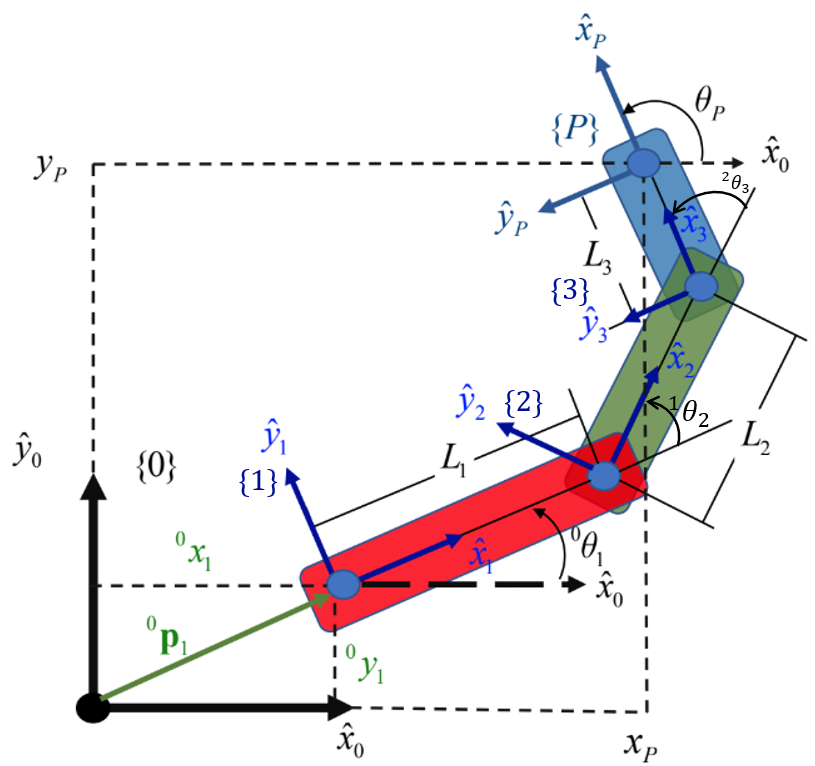

Partiendo del modelo cinemático directo de la postura, obtenido anteriormente, se plantea la cinemática inversa, recordando que el objetivo es determinar los valores de los ángulos  ${}^0{\theta \;}_1,{}^1{\theta \;}_2$y ${}^2{\theta \;}_3$, en función de ${}^0x_P$, ${}^0y_P$ (ubicación en el plano cartesiano) y ${}^0{\theta \;}_P$(orientación en el plano). 

A continuación se muestra un diagrama con las variables que se requieren para obtener el modelo inverso de manera geométrica.

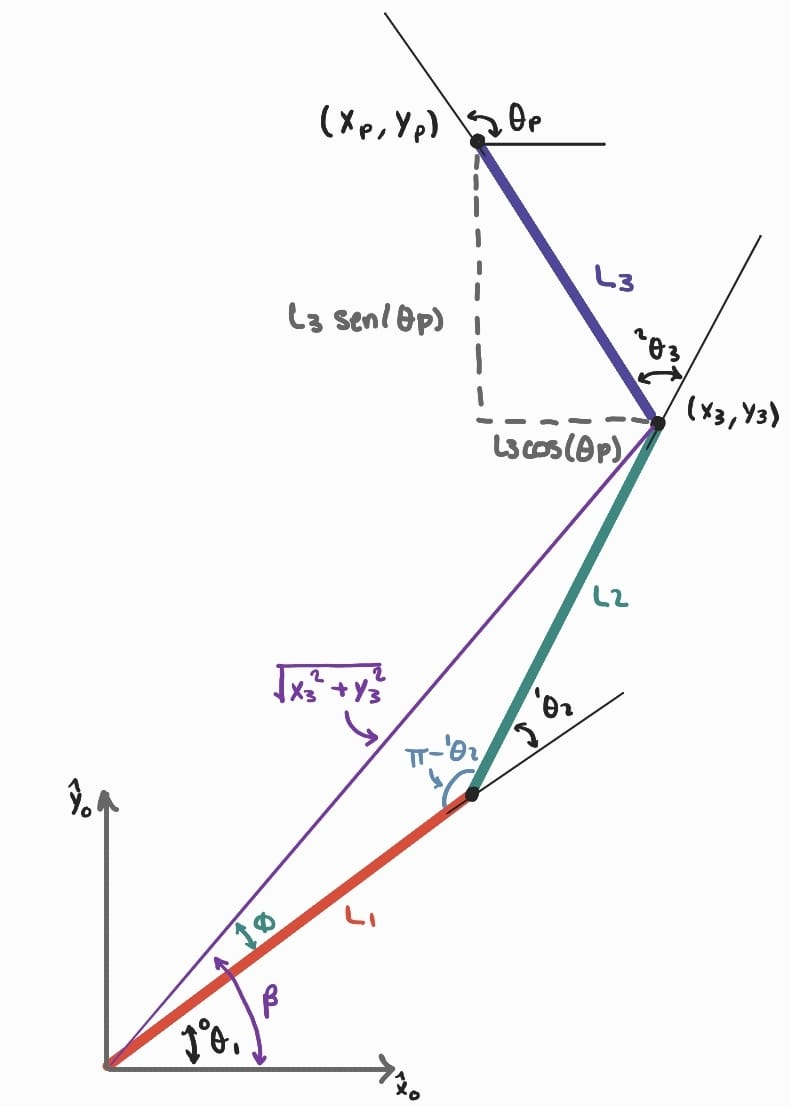

    **1.** Para obtener ${}^1{\theta \;}_2$

Se define el punto $\left(x_3 ,y_3 \right)$ a aquel ubicado en la junta rotacional que une el segundo y tercer eslabón, es decir, el final del segundo eslabón y el inicio del tercero.

Se define el  punto $\left(x_p ,y_p \right)$ a aquel ubicado en el final del tercer eslabón, es decir, en el efector final del robot. 

Se pueden describir las coordenadas del punto $\left(x_p ,y_p \right)$ de la siguiente manera: 


$$x_p =x_3 +L_3 \cos \left(\theta_P \right)$$



$$y_p =y_3 +L_3 \textrm{sen}\left(\theta_P \right)$$


Se despejan $x_3$ y $y_3$ respectivamente: 


$$x_3 =x_p -L_3 \cos \left(\theta_P \right)$$



$$y_3 =y_p -L_3 \textrm{sen}\left(\theta_P \right)$$


Se observa que se forma un triángulo con vertices $L_1$, $L_2$ y $\sqrt{x_3^2 +y_3^2 }$. Se aplica ley de cosenos para obtener el ángulo interno $\pi -{}^1{\theta \;}_2$:


$${\left(\sqrt{x_3^2 +y_3^2 }\right)}^2 =L_1^2 +L_2^2 -2L_1 L_2 \cos \left(\pi -{}^1{\theta \;}_2\right)$$


Se sabe que: $\cos \left(\pi -{}^1{\theta \;}_2\right)=-\cos \left({}^1{\theta \;}_2\right)$, entonces: 


$${\left(\sqrt{x_3^2 +y_3^2 }\right)}^2 =L_1^2 +L_2^2 -2L_1 L_2 \left(-\cos \left({}^1{\theta \;}_2\right)\right)$$


Se despeja ${}^1{\theta \;}_2$:


$${}^1{\theta \;}_2=\cos^{-1} \left(\frac{x_3^2 +y_3^2 -L_1^2 -L_2^2 }{2L_1 L_2 }\right)$$


   ** 2.** Para obtener  ${}^0{\theta \;}_1$

Se define el ángulo $\beta \;$como el ángulo que forma el vector posición $\left(x_3 ,y_3 \right)$ respecto al eje $\overset{\wedge }{x_0 }$ y se calcula con:


$$\beta =\tan \left(\frac{y_3 }{x_3 }\right)$$


Se define el ángulo $\phi \;$como el ángulo interno opuesto al vertice $L_2$ del triángulo. Usando ley de cosenos: 


$$\phi =\cos^{-1} \left(\frac{x_3^2 +y_3^2 -L_1^2 -L_2^2 }{2L_1 \sqrt{x_3^2 +y_3^2 }}\right)$$


Se observa que, el ángulo ${}^1{\theta \;}_2$ está dado por: 


$${}^0{\theta \;}_1=\beta -\phi \;$$


    **3. **Finalmente, se obtiene ${}^2{\theta \;}_3$ observando que: 


$${}^2{\theta \;}_3=\theta {\;}_P -{}^0{\theta \;}_1-{}^1{\theta \;}_2$$
 

Las siguientes exresiones, correspondientes al modelo cinemático inverso de la postura, se usarán en secciones posteriores: 


$${}^0{\theta \;}_1=\beta -\phi \;$$



$$\beta =\tan \left(\frac{y_3 }{x_3 }\right)$$



$$\phi =\cos^{-1} \left(\frac{x_3^2 +y_3^2 -L_1^2 -L_2^2 }{2L_1 \sqrt{x_3^2 +y_3^2 }}\right)$$



$${}^1{\theta \;}_2=\cos^{-1} \left(\frac{x_3^2 +y_3^2 -L_1^2 -L_2^2 }{2L_1 L_2 }\right)$$



$${}^2{\theta \;}_3=\theta {\;}_P -{}^0{\theta \;}_1-{}^1{\theta \;}_2$$
 

## Descripción del experimento (propuesta de trayectoria y simulación en Gazebo)

En esta sección se mostrará el proceso para simular el robot 3R realizando una trayectoria que pase de un punto inicial P1 a un punto final P2.

Existen diversas maneras de generar una trayectoria entre dos puntos en el espacio de trabajo de un robot. En este caso se propone usar una función de trayectoria polinomial cúbica, tambien conocida como *cubic segment trajectory. *Según Alshahrani et al. [1], este tipo de trayectoria es una de las más comúnmente empleadas en el campo de la robótica, ya que ofrece una transicion suave tanto en posición como en velocidad. 

La trayectoria se define mediante un polinomio de tercer grado de la forma: 


$$x\left(t\right)=a+\textrm{bt}+{\textrm{ct}}^2 +dt^3$$


Los coeficientes $a,b,c$ y $d$ se determinan a partir de condiciones iniciales y finales del sistema. En este caso se asumirán las siguientes condiciones: 

- $x\left(0\right)=x_0 :$ La posición inicial está dada por el punto $x_0$

- $x\left(t_f \right)=x_f :$ La posición final está dada por el punto $x_f$

- $\dot{\;x} \left(0\right)=0:$ La velocidad inicial es igual cero (el movimiento parte del reposo)

- $\dot{\;x} \left(t_f \right)=0:$ La velocidad final es igual a cero (el movimiento finaliza en reposo)

Estas condiciones permiten resolver el sistema de ecuaciones necesario para determinar los coeficientes del polinomio: 


$$P\left(0\right)=P_0 +\left(\frac{3t^2 }{t_f^2 }-\frac{2t^2 }{t_f^3 }\right)\left(P_f -P_0 \right)$$


Donde: 

- $P_0 :$ Punto inicial

- $P_f :$Punto final

- $t:$Tiempo transcurrido desde el inicio del movimiento

- $t_f :$Tiempo total que tomará completar la trayectoria desde $P_0$ a $P_f$

A continuación se definen los parámetros del robot (dimensiones de los eslabones) y los parámetros para describir la trayectoria:

% Parametros del robot
L1 = 0.5;
L2 = 0.5;
L3 = 0.3;

%Punto inicial
x_in = 0.4; %0.2
y_in = 0.2; %0.4

%Punto final
x_fin = 0.6; %0.8
y_fin = -0.3; %-0.6

% Ángulos inicial y final
theta_P_1 = 0;
theta_P_2 = 0;

%Definición de los parámetros de la trayectoria
t_total = 10;% t_f
t_in = 0.1; % incremento de tiempo
t_sim = 0:t_in:t_total; %t

% Función de interpolación polinómica de tercer orden
s = (3*(t_sim.^2)/(2*t_total^2)) - (2*(t_sim.^3)/(t_total^3));

% Puntos de la trayectoria
xp = x_in + s*(x_fin - x_in);
yp = y_in + (s.^2).*(y_fin - y_in);
theta_P = theta_P_1 + s*(theta_P_2 - theta_P_1);

A continuación se muestra una gráfica de la gemetría que va a trazar la trayectoria en el plano $\mathrm{xy}$

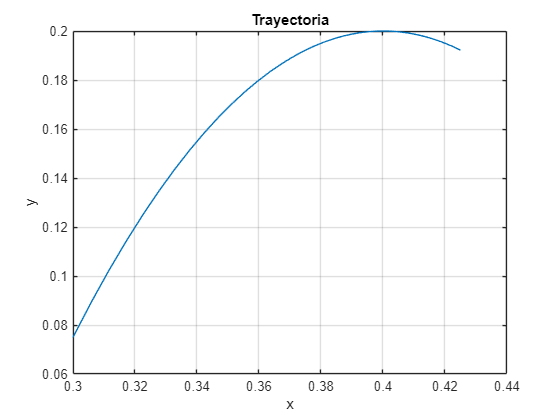

plot(xp,yp)
grid on
title('Trayectoria')
xlabel('x')
ylabel('y')

Para generar una trayectoria más interesante en el plano $\left(x,y\right)$, se optó por modificar el componente $y$ de la interpolación polinómica cúbica. En lugar de aplicar la interpolación directamente como en el caso de $x$, se elevó al cuadrado el parámetro $s$. 

En el código se definió $s$ como: 


$$s=\left(\frac{3t^2 }{t_f^2 }-\frac{2t^2 }{t_f^3 }\right)$$


Para hacer más legible el código de matlab. 

Esta modificación tiene como propósito alterar la linealidad del movimiento, introduciendo una curvatura que genera una trayectoria con forma parabólica. Aunque esta variación no responde a una necesidad física específica, se utiliza como una herramienta de experimentación para visualizar cómo pequeñas alteraciones en la función de interpolación afectan la trayectoria del efector final.

## Solucion de la cinemática

En esta sección se retoma la solución del modelo cinemático inverso de la postura del robot, para calcular el índice de manipulabilidad que tendrá el robot a lo largo de toda su trayectoria. 

Para cada instante de tiempo, se resuelve la cinemática inversa usando la posición deseada del efector final y el ángulo de orientación, obteniendo así los valores de ${}^0{\theta \;}_1$, ${}^1{\theta \;}_2$ y ${}^2{\theta \;}_3$

El índice de manipulabilidad $w$ se calcula en función del ángulo del segundo eslabón ${}^1{\theta \;}_2$ de la siguiente manera: 


$$w=|\textrm{sen}\left({}^1{\theta \;}_2\right)|$$


Este índice mide la capacidad del robot para moverse con libertad en diferentes direcciones desde una configuración dada. Un valor cercano a 0 indica pérdidas de libertad de movimiento y posibles posiciónes sigulares (aquellas en las que el robot está indeterminado), mientras que valores cercanos a 1 indica una buena capacidad de movimiento. 

También se grafica el comportamiento del ángulo ${}^1{\theta \;}_2$ respecto al tiempo durante toda la trayectoria del robot, ya que este valor tiene una influencia directa sobre el índice de manipulabilidad. 


for i=1:length(t_sim)
    % Solución de la cinematica inversa de la postura del robot

    x3 = xp(i) - L3*cos(theta_P(i));
    y3 = yp(i) - L3*sin(theta_P(i));

    theta2(i) = acos((x3^2+y3^2-L1^2-L2^2)/(2*L1*L2));

    beta = atan2(y3, x3);

    phi = acos((x3^2+y3^2+L1^2-L2^2)/(2*L1*sqrt(x3^2+y3^2)));

    theta1(i) = beta + phi; 

    theta3(i) = theta_P(i) - theta1(i) - theta2(i);
    % calculo de w[i] 

    w(i) = abs(sin(theta2(i)));

end

## Resultados

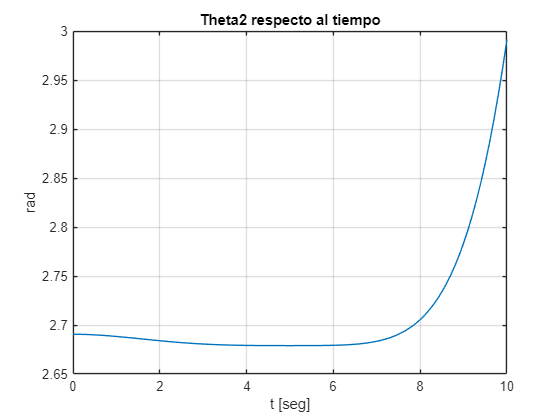

plot(t_sim, theta2)
grid on
title('Theta2 respecto al tiempo')
xlabel('t [seg]')
ylabel('rad')

En la gráfica de ${}^1{\theta \;}_2$ respecto al tiempo se puede observar que, al comenzar la trayectoria, ${}^1{\theta \;}_2$ tiene un valor cercano a 2.7 radianes, tiene una ligera disminución para el segundo 6 y crece progresivamente a partir de este punto. ${}^1{\theta \;}_2$ comienza a aumentar de manera gradual y posteriormente de forma más acelerada conforme se acerca al final de la trayectoria. 

El valor máximo final que alcanza ${}^1{\theta \;}_2$ es cercano a 3 radianes. 

Este comportamiento indica que, al inicio, el robot modifica su configuración de forma contínua y suave, esto es favorable para evitar movimientos bruscos. El valor de ${}^1{\theta \;}_2$ se mantiene dentro de un rago estrecho, aproximadamente entre 2.68 y 3 radianes. Al final de la trayectoria, el aumento del ángulo refleja una flexión de la segunda articulación, y es necesaria para que el efector final llegue a la posición deseada. 

Se deberá analizar la gráfica del índice de manipulabilidad respecto al tiempo para tener conclusiones más precisas respecto a la calidad y viabilidad del movimiento: 

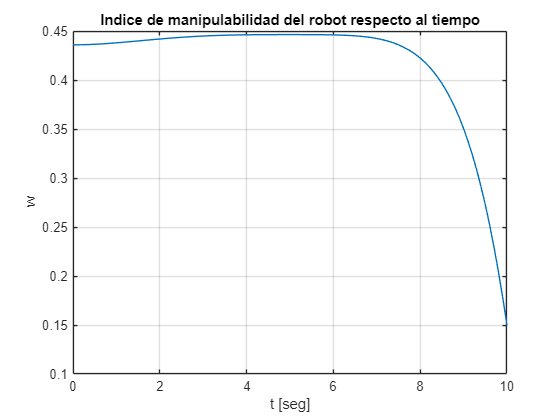

plot(t_sim, w)
grid on
title('Indice de manipulabilidad del robot respecto al tiempo')
xlabel('t [seg]')
ylabel('w')

En la grafica del índice de manipulabilidad se puede observar que, al inicio, el índice se mantiene relativamente constante, con un valor cercano a 0.44, lo que indica buena capacidad de maniobra. Se mantiene estable durante los primeros segundos y aumenta ligeramente hasta el segundo 6. 

A partir de este momento, coincidiendo con el incremento del ángulo ${}^1{\theta \;}_2$, el índice de manipulabilidad comienza a disminuir progresivamente hasta llegar a un valor mínimo de 0.15 al final de la trayectoria. Esta caída representa una pérdida significativa de movilidad, lo cual sugiere que el robot se acerca a una configuración menos favorable o incluso cercana a una singularidad.

El índice de manipulabilidad se encuentra entre un valor de 0.15 y 0.44 a lo largo de toda la trayectoria. Se puede concluir que el robot presenta una buena capacidad de movimiento en la primer mitad de su trayectoria, sin embargo, conforme avanza hacia el final, su libertad de movimiento disminuye notablemebte, lo cual podría limitar su desempeño o requerir un mayor cuidado en esa configuración. 

## Simulación en Gazebo y RViz

Primero, se creó un archivo de nodo `scara_trayectoria_cubica.py`, el cual contendrá la lógica para enviar la trayectoria cúbica al robot SCARA mediante el tópico `/scara_trajectory_controller/joint_trajectory`. Para desarrollar este código se usó el archivo `scara_tray_line.py` como plantilla y se modificó la función "invk_sol", donde se definió la ecuación de la trayectoria cúbica. Además, se modificó la función "trayectory_cbck" para establecer los puntos inical y final de la trayectoria. 

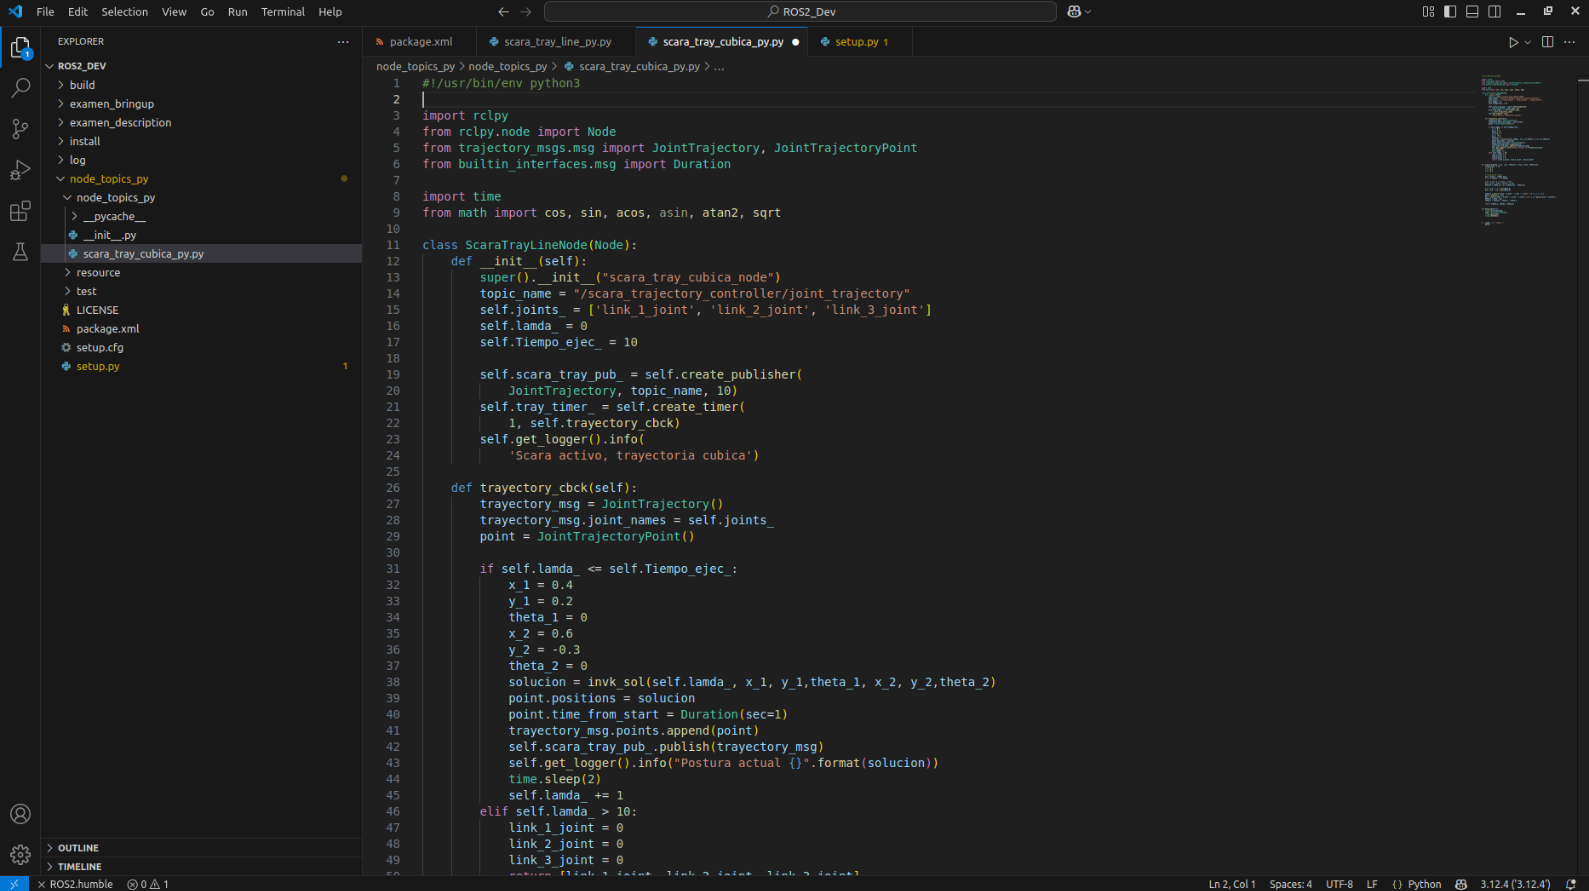

El código de este nodo es el siguiente: 

`#!/usr/bin/env python3`

`import rclpy`

`from rclpy.node import Node`

`from trajectory_msgs.msg import JointTrajectory, JointTrajectoryPoint`

`from builtin_interfaces.msg import Duration`

`import time`

`from math import cos, sin, acos, asin, atan2, sqrt`

`class ScaraTrayLineNode(Node):`

`    def __init__(self):`

`        super().__init__("scara_tray_cubica_node")`

`        topic_name = "/scara_trajectory_controller/joint_trajectory"`

`        self.joints_ = ['link_1_joint', 'link_2_joint', 'link_3_joint']`

`        self.lamda_ = 0`

`        self.Tiempo_ejec_ = 10`

`        self.scara_tray_pub_ = self.create_publisher(`

`            JointTrajectory, topic_name, 10)`

`        self.tray_timer_ = self.create_timer(`

`            1, self.trayectory_cbck)`

`        self.get_logger().info(`

`            'Scara activo, trayectoria cubica')`

`    def trayectory_cbck(self):`

`        trayectory_msg = JointTrajectory()`

`        trayectory_msg.joint_names = self.joints_`

`        point = JointTrajectoryPoint()`

`        if self.lamda_ <= self.Tiempo_ejec_:`

`            x_1 = 0.4`

`            y_1 = 0.2`

`            theta_1 = 0`

`            x_2 = 0.6`

`            y_2 = -0.3`

`            theta_2 = 0`

`            solucion = invk_sol(self.lamda_, x_1, y_1,theta_1, x_2, y_2,theta_2)`

`            point.positions = solucion`

`            point.time_from_start = Duration(sec=1)`

`            trayectory_msg.points.append(point)`

`            self.scara_tray_pub_.publish(trayectory_msg)`

`            self.get_logger().info("Postura actual {}".format(solucion))`

`            time.sleep(2)`

`            self.lamda_ += 1`

`        elif self.lamda_ > 10:`

`            link_1_joint = 0`

`            link_2_joint = 0`

`            link_3_joint = 0`

`            return [link_1_joint, link_2_joint, link_3_joint]`

`def invk_sol(param, x_in, y_in, theta_in, x_fin, y_fin, theta_fin):`

`    Tiempo_ejec_ = 10`

`    L_1 = 0.5`

`    L_2 = 0.5`

`    L_3 = 0.3`

`    # Trayectoria cúbica`

`    tau = param / Tiempo_ejec_`

`    s = 3 * tau**2 - 2 * tau**3  `

`    x_P = x_in + s * (x_fin - x_in)`

`    y_P = y_in + s**2 * (y_fin - y_in)`

`    theta_P = theta_in + s * (theta_fin - theta_in)`

`    x_3 = x_P - L_3 * cos(theta_P)`

`    y_3 = y_P - L_3 * sin(theta_P)`

`    theta_2 = acos((x_3**2 + y_3**2 - L_1**2 - L_2**2) / (2 * L_1 * L_2))`

`    beta = atan2(y_3, x_3)`

`    psi = acos((x_3**2 + y_3**2 + L_1**2 - L_2**2) / (2 * L_1 * sqrt(x_3**2 + y_3**2)))`

`    theta_1 = beta - psi`

`    theta_3 = theta_P - theta_1 - theta_2`

`    return [theta_1, theta_2, theta_3]`

`def main(args=None):`

`    rclpy.init(args=args)`

`    node = ScaraTrayLineNode()`

`    rclpy.spin(node)`

`    rclpy.shutdown()`

`if __name__ == "__main__":`

`    main()`

Se agregó el archivo al código de `setup.py`:

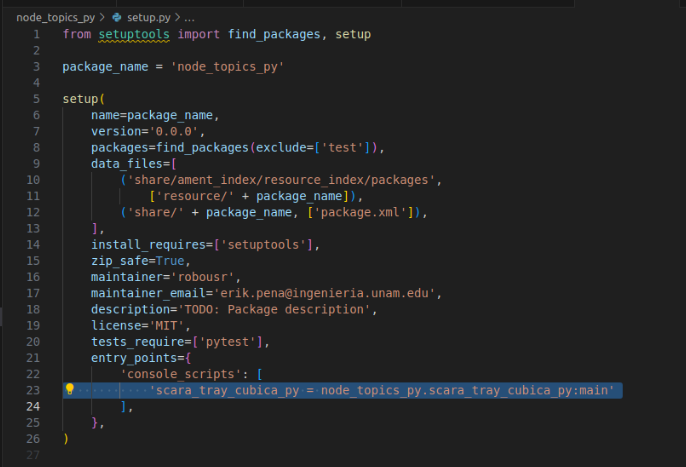

Finalmente se construyó el paquete con el siguiente comando desde el espacio de trabajo: 

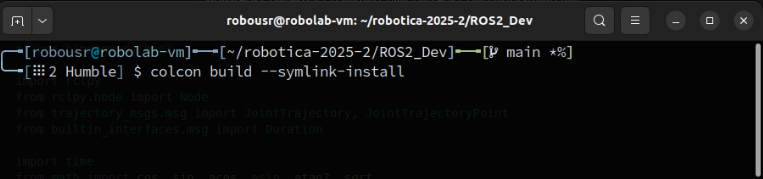

Se utilizó una máquina virtual Para lanzar la simulación del robot, se empleó el archivo de lanzamiento (launch) `roberto_pos_controller_scara.launch.py `configurado previamente durante el curso de Robótica del presente semestre. Este archivo permite inicializar el entorno de simulación y visualizar el robot SCARA descrito anteriomente en URDF, tanto en Gazebo como en RViz, de forma simultánea:

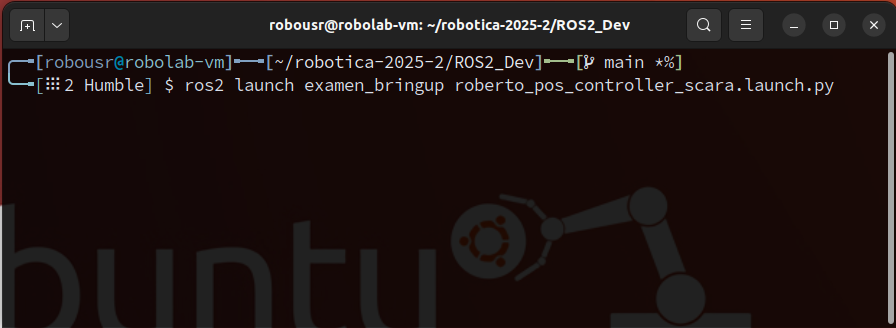

Al ejecutar el comando, se abre Gazebo y RViz con el archivo del robot SCARA: 

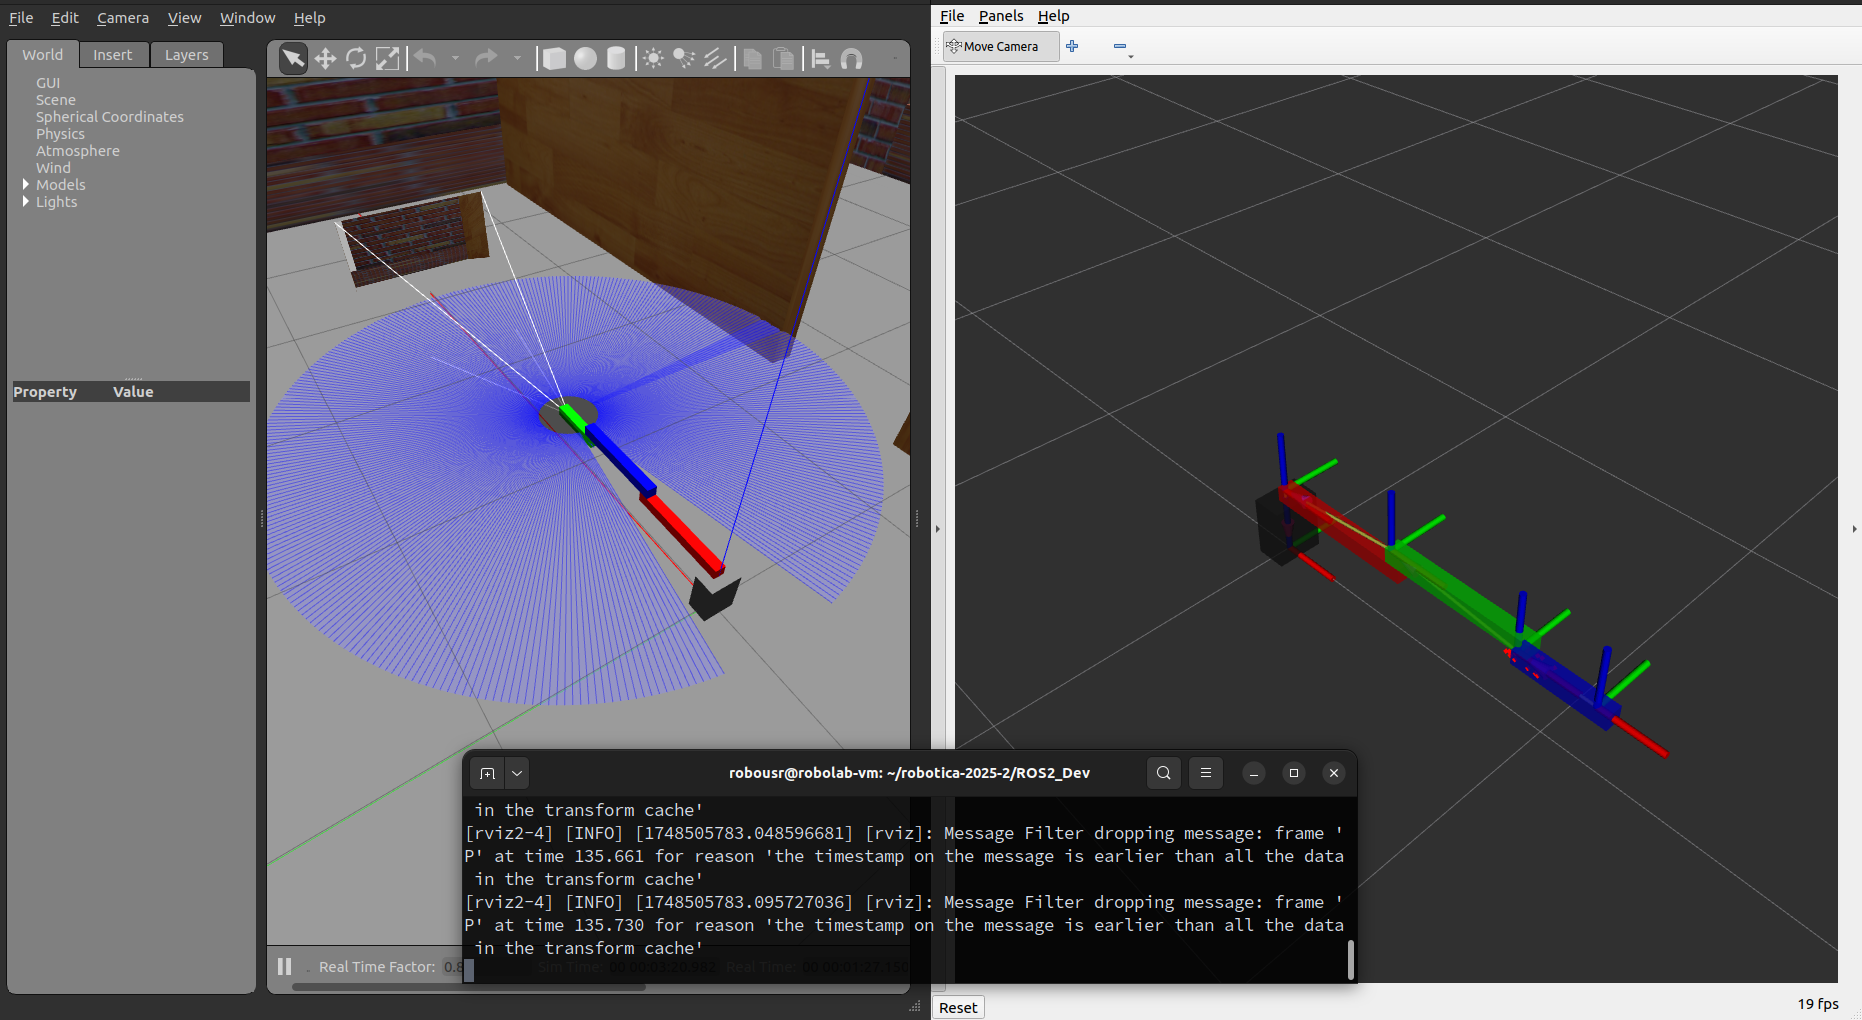

Se abre una nueva terminal y se ejecuta el archivo de nodo `scara_trayectoria_cubica.py:`

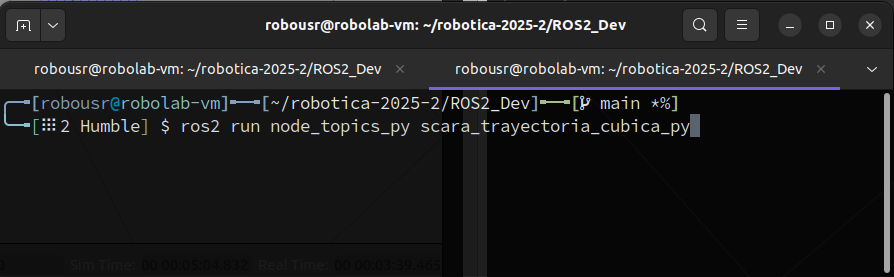

Se observa cómo el robot SCARA realiza el movimiento de la trayectoria planteada: 

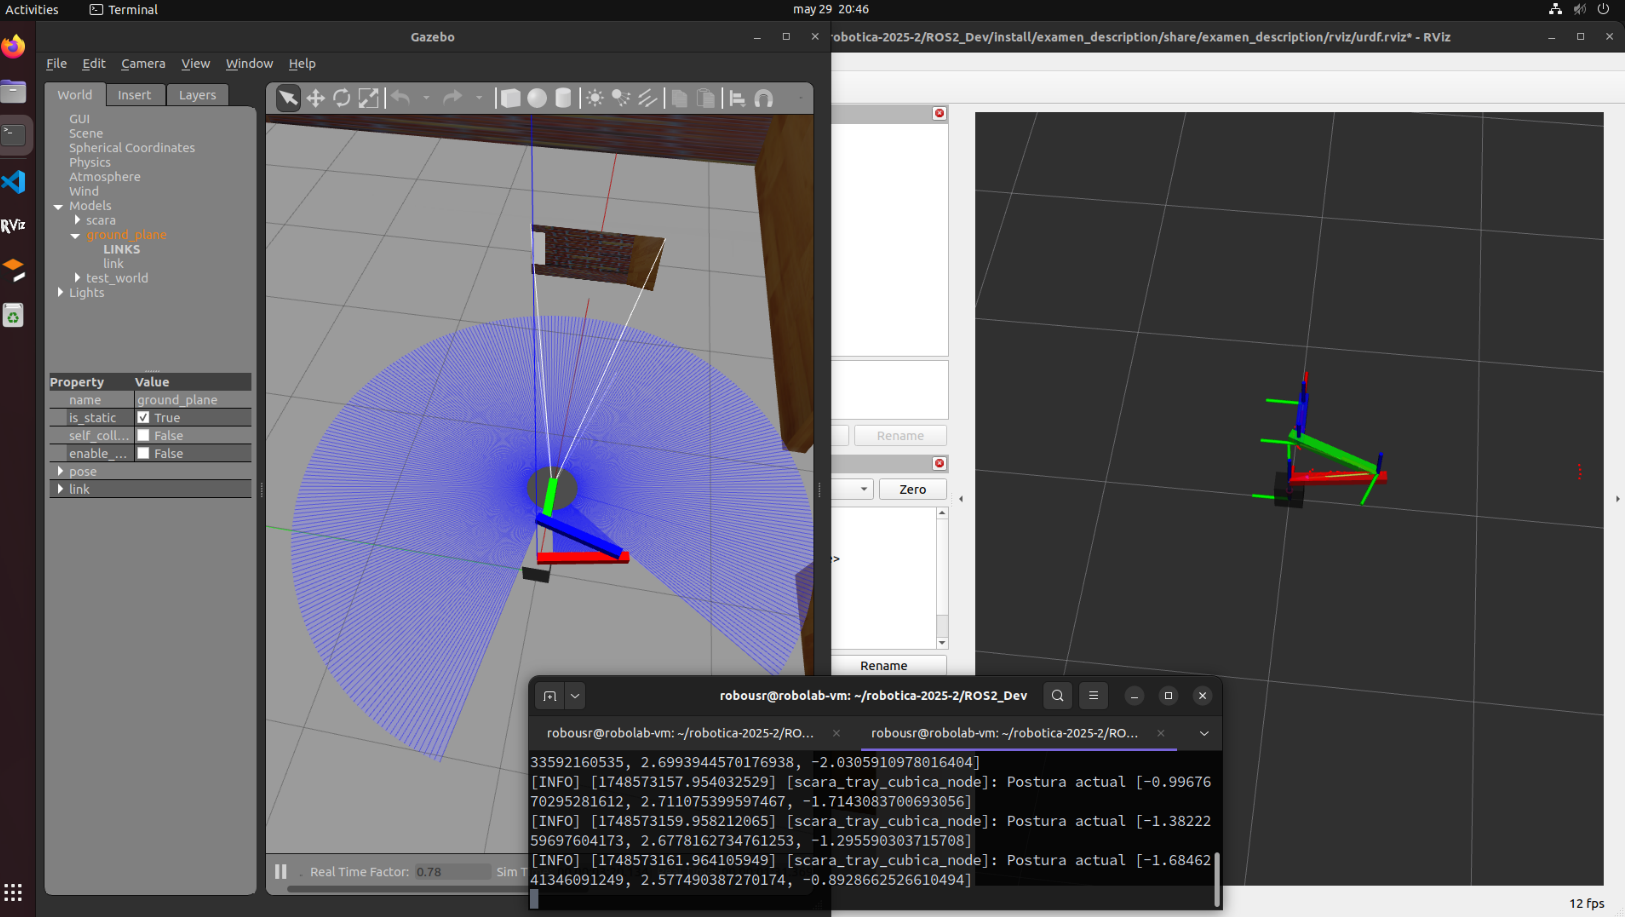

A continuación se encuentran enlaces a videos para observar el movimiento del robot al ejecutar la trayectoria:

- [Video de simulación 1](https://youtu.be/-gEnEOQBczg)

- [Video de simulación 2](https://youtu.be/tAZdo_nni7E)

## Conclusiones

- Castañeda Coria Brenda Scarlett

El análisis de un robot scara 3R se realizó mediante la implementación de los conceptos teóricos y prácticos para realizar el modelado del robot y posteriormente la simulación. Primero, se desarrolló el archivo URDF en el que se representaron elementos como la geometría, la inercia y la parte de colisión del robot, permitiendo visualizarlo en un entorno virtual.

Para lograrlo fue necesario construir los modelos matemáticos que describieran el comportamiento del robot en términos de cinemática directa de la postura y velocidades. Una vez hecho esto, también se realizó la cinemática inversa para determinar la configuración necesaria para lograr una posición deseada en el espacio de trabajo.

Una vez realizado el planteamiento teórico se elige una trayectoria. Mediante el modelo realizado anteriormente se verificó que la trayectoria fuera adecuada para el robot, es decir, que pudiera ser realizada de manera satisfactoria bajo las condiciones dadas. Un factor importante fue el índice de manipulabilidad, que evalúa la capacidad del robot para moverse en distintas direcciones de acuerdo a su configuración articular. Calcularlo fue indispensable para identificar si el robot presentaba limitaciones o singularidades en la trayectoria. Esto no sólo permite identificar errores y configuraciones desfavorables, sino que también puede ser utilizado para optimizar trayectorias y garantizar la precisión y estabilidad del movimiento.

Una vez hecho esto, se verificó la simulación mediante Gazebo, integrando los paquetes necesarios. Este permitió observar el comportamiento del robot de acuerdo a las trayectorias programadas en sus juntasa. Esta etapa es fundamental para validar el modelo matemático demostrando que se cumple lo planteado. 

En conclusión, el análisis del comportamiento de un robot siguiendo esta metodología ayuda a complementar y evidenciar los resultados teóricos, integrando los conocimientos de cinemática, análisis de manipulabilidad y herramientas de simulación como ROS, RViz y Gazebo para ofrecer una experiencia completa de diseño y validación de un robot manipulador.

- Juárez Ugalde Ricardo

Este trabajo consistió en retomar el modelo matemático (específicamente el modelo cinemático de la postura) desarrollado en el primer examen parcial de la asignatura, para implementar un control de trayectoria en un robot SCARA 3R mediante una simulación en Gazebo y RViz usando ROS2. Se propuso una trayectoria que permiete al efector final del robot desplazarce desde un punto inicial hasta un punto final. La trayectoria elegida fue de tipo cúbica polinomial, y se modificó intencionalmente el valor de la coordenada en y para generar una trayectoria con forma geométrica similar a la de una parábola. 

Se abordó el desarrollo del modelo cinemático inverso de la postura a partir del modelo directo obtenido en el primer examen parcial, usado un método geométrico basado en principios de trigonometría. Este proceso fue esencial para obtener las expresiones analíticas que permiten calcular los ángulos de los eslabones en función de las coordenadas cartesianas del efector final y las dimensiónes del robot. 

Posteriormente, se modificó un archivo de nodo en Phyton, previamente desarrollado en clase, para cargar en la simulación tanto la ecuación de la trayectoria propuesta como la solución del modelo cinemático inverso de la postura, logrado así que el robot ejecutara el movimiento deseado. Se observó que el robot SCARA 3R fue capaz de realizar el desplazamiento de manera correcta. El efector final trazó una trayectoria que, aunque sutil, mostraba una ligera curvatura parabólica. 

Se generó una gráfica que representa el índice de manipulabilidad del robot en función del tiempo, durante el desarrollo de la trayectoria. En esta gráfica se observó que el índice se mantiene en valores relativamente buenos (alrededor de 0.44) durante la mayor parte del movimiento, lo cual indica una buena capacidad de maniobra. Sin embargo, en los últimos segundos, el índice disminuye bruscamente hasta alcanzar un valor de 0.15 al final de la trayectoria. Esto sugiere que el robot se acerca a una configuración desfavorable cuando llega al punto final de la trayectoria. 

El desarrollo de este trabajo proporcionó una experiencia valiosa en la implementación de modelos matemáticos con herramientas de simulación. Se logró validar la viabilidad de una trayectoria propuesta para un robot SCARA 3R, y se identificó una zona crítica relacionada con la manipulabilidad. Lo anterior es esencial pra futuros trabajos relacionados con el diseño de trayectorias, control y modelado matemático de robots. 

- Parra García Horacio

A lo largo de este trabajo, se aplicaron los conceptos vistos en el curso y se retomaron los conceptos básicos de la ingeniería. Se contruyeron nuestros archivos URDF que nos ayudaron a poder lograr nuestro espacio de simulación y con la ayuda de Rviz y Gazebo integraron y mostraron de una manera más clara como es que se realizan los movimientos de nuestro robot scara el cual se compone de 3 eslabones, dichas simulaciones se pueden apreciar en los videos anexados, donde se ve el movimiento controlado y preciso del robot. La trayectoria que generó fue elegida estratégicamente, la cual fue la tipo cúbica polinomial pero se modificó el punto en y para generar más una trayectoria tipo parábola. En un panorama más general los cálculos de la cinemática inversa y el índice de manipulabilidad fueron claves para poder llevar a cabo esos movimientos que generó nuestro robot, la cinemática inversa nos ayudó a controlar el ángulo de la posición de nuestro robot y el índice de manipulabilidad a poder generar un movimiento más factible con esto me refiero a que si es más cercano a 1 el robot podrá efectuar el movimiento de manera exitosa aunque en lo ideal sería que siempre sea lo más cercano a 1 en la vida real eso es casi imposible, tal como vimos en nuestra gráfica el valor máximo que obtuvimos fue de 0.44 y después bajó de manera rápida a 0.15 esto para terminar la trayectoria. 

La realización de este proyecto me ayudó a poder entender cómo es que funciona un robot scara y que es lo que se considera para que en un futuro en la industria tenga las herramientas necesarias para decidir si puede efectuar su trabajo de manera adecuada o si es posible o no. Por último me gustaria terminar afirmando que se cumplió nuestro objetivo de forma exitosa respecto a nuestra hipótesis planteada.

## Referencias

[1] S. A. Alshahrani, H. Diken, and A. A. N. Aljawi, “Optimum trajectory function for minimum energy requirements of a spherical robot,” *Proc. 6th Saudi Eng. Conf.*, vol. 4, pp. 613, 2002.